# Równania nieliniowe

Przykładowa implementacja metody Newtona.

Definicja funkcji, której miejsce zerowe jest poszukiwane.

F = @(x) cos(x) - x;

Funkcja numerycznie obliczająca wartośc pochodnej w punkcie

h=10^-6;
dF = @(x) 0.5*(F(x+h)-F(x-h))/h;

Okrślenie przybliżenia początkowego i wartości dokładności rozwiązania.

x0 = 2; % punkt startowy

epsx = 0.001; % dokładność rozwiązania względem kolejnych przybliżeń
epsf = 0.001; % dokładność rozwiązania względem wartości funkcji
maxIter = 100;


Metoda Newtona:

x1 = x0;
x0 = x0 + 2*epsx;
while abs(x0-x1) > epsx || abs(F(x1))>epsf
    x0 = x1 ;
    x1 = x0 - F(x0)/dF(x0)
end

x1 = 0.7345

x1 = 0.7391

x1 = 0.7391

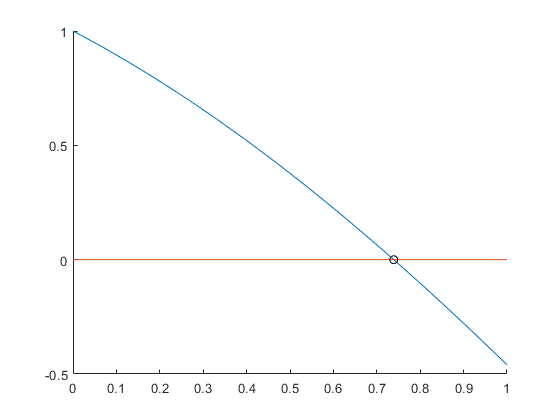


newplot()
hold on
fplot(F,[0,1])
fplot(0,[0,1])
scatter(x1,0,"black")
hold off